Bewegung der MHT Einheit

Bereich der Kollisionsfrein bewegung

figure(1)
% motionfield
mf= [0 0 0   NaN NaN; ...
            10 -5 20  NaN NaN; ...
            20 -10 30  NaN NaN; ...
            30 -20 40 0 0; ...
            40 -30 30  -10 20; ...
            50 -40 35  -15 10; ...
            60 -30 40   -5 5 ; ...
            70 -60 60   -30 30; ...
            80 -70 50 0 0; ...
            90 -60 55 NaN NaN; ...
            100 -50 50 NaN NaN];
plot(mf(:,1),mf(:,[2,3, 4, 5]),'b*' )
hold on
~isnan(mf(:,4));
xx = 0:1:100;
x=mf(:,1)

x =      0
    10
    20
    30
    40
    50
    60
    70
    80
    90


for i=2:3
y =mf(:,i);
yy = spline(x,y,xx);
plot(xx,yy,'b' )
end
xx = 30:80;
for i=4:5
x=mf(~isnan(mf(:,4)),1);
y=mf(~isnan(mf(:,4)),i);
yy = spline(x,y,xx);
plot(xx,yy,'b' )
end 
grid on
hold on


Gnerate random Pos

n=0;
x=rand()*100;
y=rand()*200-100;
while ~inArea(mf, x,y)
    x=rand()*100;
    y=rand()*200-100;
    if n>100
        break 
    end
        n=n+1; 
  
end
    plot(x,y,'ro')
    xlabel('\theta 1')
    ylabel('\theta 2')
    title('Allowed Areas')
    
    
   

    

Find Path home

   p=zeros(size(mf,1),2);
    for i=1:size(mf,1)
       if isnan(mf(i,4)) 
         p(i,:)= [(mf(i,2)+mf(i,3))/2, (mf(i,2)+mf(i,3))/2];
        else
         p(i,:)= [(mf(i,2)+mf(i,4))/2 , (mf(i,3)+mf(i,5))/2];
        end
     end
     plot(mf(:,1),p,'g')
     plot(mf(:,1),p,'g+')
     
 
 
     hold off
     
     
     

Definiton der Geometrie

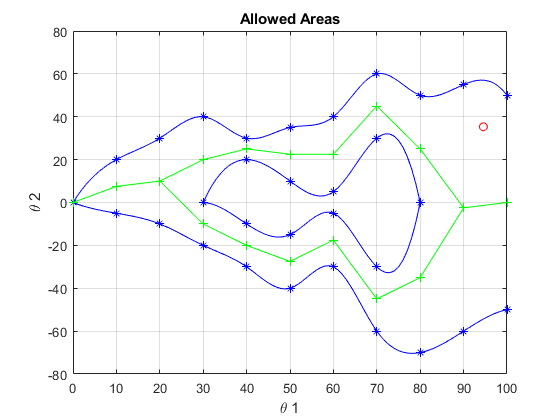

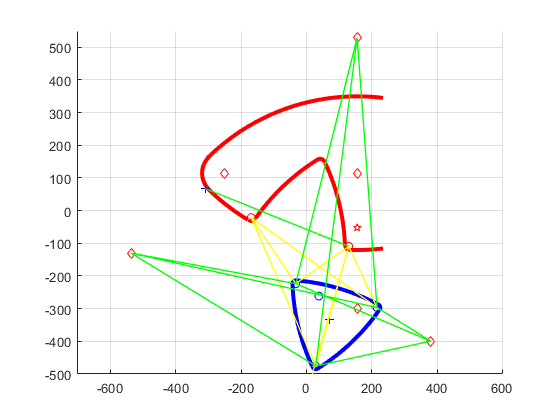

kol = 0

kol = 0

kol = 0

kol = 0

kol = 0

kol = 0

kol = 0

kol = 0

kol = 0

kol = 0

kol = 0

kol = 0

kol = 0

kol = 1

kol = 2

kol = 2

kol = 1

kol = 0

kol = 0

kol = 0

kol = 1

kol = 1

kol = 1

kol = 1

kol = 1

kol = 1

kol = 1

kol = 2

kol = 3

kol = 3

kol = 3

kol = 3

kol = 3

kol = 2

kol = 1

kol = 1

kol = 0

kol = 0

kol = 0

kol = 0

kol = 0

kol = 0

kol = 0

kol = 0

kol = 0

kol = 0

kol = 0

kol = 0

kol = 0

kol = 0

kol = 1

kol = 1

kol = 3

kol = 1

kol = 1

kol = 0

kol = 0

kol = 0

kol = 1

kol = 1

kol = 1

kol = 1

kol = 1

kol = 1

kol = 2

kol = 3

kol = 3

kol = 3

kol = 3

kol = 3

kol = 2

kol = 1

kol = 1

kol = 0

kol = 0

kol = 0

kol = 0

kol = 0

kol = 0

kol = 0

kol = 0

kol = 0

kol = 0

kol = 0

kol = 0

kol = 0

kol = 0

kol = 0

kol = 1

kol = 3

kol = 2

kol = 1

kol = 0

kol = 0

kol = 0

kol = 1

kol = 1

kol = 1

kol = 1

kol = 1

kol = 1

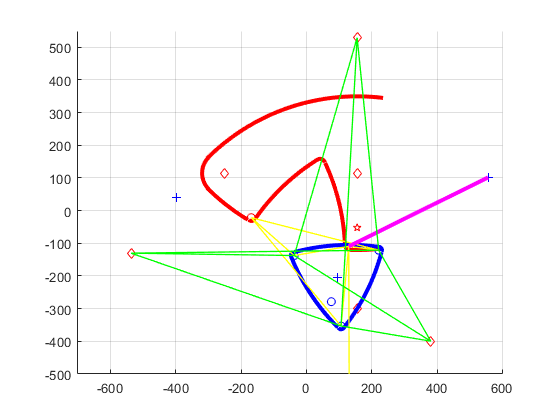

Error using plot
Unrecognized property lineWidtht for class Line.

Error in findHomePath_V2>checkPoints (line 584)
     plot([P1(1)  P2(1)],[P1(2)  P2(2)],col,'lineWidtht',lw);

Error in findHomePath_V2>checkCollision (line 544)
    nk =

    rd= 650;     % Ausenradius
    rd1= rd-10;  % Radius Eckpunkte
    ld = 259.2; % Basisbreit MHT
    
     kx=22; % Krorrekturlänge
     
    hd = ld*sqrt(3)/2; % höhe MHT
    hm= ld/(2*sqrt(3)); % Mittelpunktslage MHT
    pd = asind(ld/(2*rd1)); % Bogenwinkel MHT
    rd2= sqrt(rd1*rd1-(ld/2)*(ld/2)); % Höhe über Sekante bis Mittelpunkt
    hr= rd2-hm; % Höhe Mittelpunkt
    pr= -pd:pd; % Bogen für MHT
    ox= 25.0;   % Lage x Drehpunkt MHT
    oy= 148.14-hm; % Lage x Drehpunkt MHT
    lmb = 161.78  + kx*sind(-16.43);  % Abstand x MHT, Bass
    lmh = -30.79  - kx*cosd(-16.43);  % Abstand x MHT, Bass
    alfa0=-asind(lmb/(hr));  % Drehung MHD in Nullstellung
    alfa1= alfa0+120;
   
    mBox.rd=rd;
    mBox.pd=pd;

    mBox.alfa0=alfa0;
    mBox.alfa1 = alfa1;
     
    mBox.Po=[ox, oy];
    mBox.P0=[0, 0];
    mBox.P1=[0, hd-hm];
    mBox.P2=[-ld/2, -hm];
    mBox.P3=[ ld/2, -hm];
    mBox.M1=[ 0,            hr];
    mBox.M2=[ hr*cosd(-30), hr*sind(-30)];
    mBox.M3=[-hr*cosd(-30), hr*sind(-30)];
    mBox.Po= rot(mBox.Po, alfa1);
    mBox.P1= rot(mBox.P1, alfa1);
    mBox.P2= rot(mBox.P2, alfa1);
    mBox.P3= rot(mBox.P3, alfa1);
    mBox.M1= rot(mBox.M1, alfa1);
    mBox.M2= rot(mBox.M2, alfa1);
    mBox.M3= rot(mBox.M3, alfa1);
    pr=pr+alfa1;
    mBox.pr=pr;
      
    mBox.M4b=[lmb, -300]; % Mittelpunkt für Ausenkreis
    lhr= hr*(1.0-cosd(alfa0));
    ym=  (hr + mBox.M4b(2))/2-lhr/2;
    mBox.M5=[-250,ym];   % Mittelpunkt hinterer Boxabschluss
    mBox.M0=[lmb, ym]; % Box Center
    mBox.M4a =   [mBox.M4b(1), 2*ym-mBox.M4b(2)];

 
     mBox.k1.m= mBox.M1;
     mBox.k1.r= rd;
     mBox.k1.p= pr-90;
     mBox.k1.b=true;

     mBox.k2.m= mBox.M2;
     mBox.k2.r= rd;
     mBox.k2.p= pr+150;
     mBox.k1.b=true;

     mBox.k3.m= mBox.M2;
     mBox.k3.r= rd;
     mBox.k3.p= pr+30;
     mBox.k1.b=true;

     mBox.kx1.m= mBox.M1;
     mBox.kx1.r= rd1;
     mBox.kx1.p= pr-90;
     mBox.kx1.b=false;

     mBox.kx3.m= mBox.M3;
     mBox.kx3.r= rd1;
     mBox.kx3.p= pr+30;
     mBox.kx3.b=false;
     
     mBox.kx4.m=mBox.M4a;
     mBox.kx4.r= rd1;
     mBox.kx4.p= 83:1:92; % Bogen Ausenkreis
     mBox.kx4.b=true;

     mBox.kx5.m=mBox.M4a;
     mBox.kx5.r= rd1;
     mBox.kx5.p= 121:1:135; % Bogen Ausenkreis
     mBox.kx5.b=true;

    figure(4)
    axis equal
    grid on
    hold on
    % PlotBox()
    %hold on
    %plot([mBox.Po(1), mBox.P1(1), mBox.P2(1), mBox.P3(1) ],...
    %     [mBox.Po(2), mBox.P1(2), mBox.P2(2), mBox.P3(2) ],'bo');
    %plot([mBox.P0(1), mBox.M1(1), mBox.M2(1), mBox.M3(1) ],...
    %     [mBox.P0(2), mBox.M1(2), mBox.M2(2), mBox.M3(2) ],'b+');

    %plot(mBox.M1(1)+rd*cosd(pr-90), mBox.M1(2)+rd*sind(pr-90),'b','LineWidth',3);
    %plot(mBox.M2(1)+rd*cosd(pr+150),mBox.M2(2)+rd*sind(pr+150),'b','LineWidth',3);
    %plot(mBox.M3(1)+rd*cosd(pr+30), mBox.M3(2)+rd*sind(pr+30),'b','LineWidth',3);
    %rp=10;
    %pp=(-60:10:60)+alfa0;
    %plot(mBox.P1(1)+rp*cosd(pp+90+120), mBox.P1(2)+rp*sind(pp+90+120),'b','LineWidth',3);
    %plot(mBox.P2(1)+rp*cosd(pp+90-120), mBox.P2(2)+rp*sind(pp+90-120),'b','LineWidth',3);
    %plot(mBox.P3(1)+rp*cosd(pp+90), mBox.P3(2)+rp*sind(pp+90),'b','LineWidth',3);
    
    %kx=22;
    %   lmb = 161.78  + kx*sind(-16.43);  % Abstand x MHT, Bass
    %   lmh = -30.79  - kx*cosd(-16.43);  % Abstand x MHT, Bass
    mBox.MB1=mBox.M1;
    mBox.MB3=mBox.M3;
    mBox.PB3=mBox.P3;

    mBox.PoB =  [ lmb, lmh];
    mBox.Po1= mBox.PoB +[-25.73,  -57.34];
    mBox.Po2 = rotX(mBox.M4a, mBox.Po1, -(2*mBox.pd+4.4+0.4));
    mBox.M5=[-250,ym];   % Mittelpunkt hinterer Boxabschluss
    mBox.M0=[lmb,ym]; % Box Center
    mBox.plot=3;
    
    step=5;
     theta1= 75:step:105;
     theta2= -135:step:45;
       nx=length(theta1);
       ny=length(theta2);
      flt= ones(nx,ny);
     for w1=1:nx
          for w2=1:ny

    clf;
     axis equal
     grid on
     hold on
    xlim([-700 600])
    ylim([-500 550])
    plotBassBox(mBox);
       
       
    rBox= rotateBox(mBox, theta1(w1), theta2(w2));
    Plot_Box(rBox);
    kol=checkCollision(rBox)
    drawnow
     flt(w1, w2)=kol;
          end
     end

     figure(5);
     [X,Y]=meshgrid(theta2,theta1);
      surf(X,Y,flt);
      
    % Plot BassBox
    %rd2=rd+5;
    %prb = -pd-1:pd+1;
    %prb=prb+mBox.alfa1;
    %plot(mBox.M1(1)+rd2*cosd(prb-90), mBox.M1(2)+rd2*sind(prb-90),'y','LineWidth',1);
    %plot(mBox.M1(1)+rd2*cosd(prb-114), mBox.M1(2)+rd2*sind(prb-114),'y','LineWidth',1);
    %plot(mBox.M1(1)+rd2*cosd(prb-65), mBox.M1(2)+rd2*sind(prb-65),'y','LineWidth',1);

    %plot(mBox.M1(1)+rd2*cosd(prb-90), mBox.M1(2)+rd2*sind(prb-90),'r','LineWidth',3);
    %plot(mBox.M3(1)+rd2*cosd(prb+30), mBox.M3(2)+rd2*sind(prb+30),'r','LineWidth',3);
    % rp=15;
    %plot(mBox.P3(1)+rp*cosd(pp+90), mBox.P3(2)+rp*sind(pp+90),'r','LineWidth',3);

    %mBox.M4=[lmb, -300]; % Mittelpunkt für Ausenkreis
    %lhr= hr*(1.0-cosd(alfa0))
    %ym=  (hr + mBox.M4(2))/2-lhr/2;
    %rb=69;   % Radius Boxabschluss
    %ps=85:1:135; % Bogen Ausenkreis

    %plot([mBox.M0(1),mBox.M4(1),mBox.M4(1),mBox.M5(1)],[mBox.M0(2),mBox.M4(2),2*ym-mBox.M4(2),mBox.M5(2)], 'rd')
    % Box aussen oben
    %plot(mBox.M4(1)+rd*cosd(ps), mBox.M4(2)+rd*sind(ps),'r','LineWidth',3);
    % Box aussen unten
    %plot(mBox.M4(1)+rd*cosd(ps), 2*ym-mBox.M4(2)-rd*sind(ps),'r','LineWidth',3);
   % mBox.M4a =   [mBox.M4(1), 2*ym-mBox.M4(2)];
     % Box Abschluss
    % pa=135:1:225;
    %plot(mBox.M5(1)+rb*cosd(pa), mBox.M5(2)+rb*sind(pa),'r','LineWidth',3);

     %   mBox.PoB(1)=   lmb;
     %   mBox.PoB(2)=   lmh;
     %   mBox.Po1(1)= mBox.PoB(1) -25.73;
     %   mBox.Po1(2)= mBox.PoB(2) -57.34;
     %   mBox.Po2 = rotX(mBox.M4a, mBox.Po1, -(2*pd+4.4+0.4));

      
    %plot([ mBox.PoB(1)],[ mBox.PoB(2)], 'rp')
    %plot([ mBox.Po1(1),  mBox.Po2(1)],[ mBox.Po1(2),  mBox.Po2(2)], 'go')
    %     rp=10;
    %plot(mBox.Po1(1)+rp*cosd(pp-110), mBox.Po1(2)+rp*sind(pp-110),'r','LineWidth',3);
    %plot(mBox.Po2(1)+rp*cosd(pp-60),  mBox.Po2(2)+rp*sind(pp-60),'r','LineWidth',3);

    l=norm(mBox.PoB-mBox.Po)
  %  axis equal
  %  grid on
  %  plotBassBox(mBox);
  %  hold off
  %  mBox

Collision check

  
     
%     figure(2)
%     box.plot=3; % Plot etherything
%     x1=0; y1=0;
%     
%     
%     
%     
%     
%     box.x1=0; box.y1=0;
%     box.x2=0.37; box.y2=0;
% 
%     box.k1.m(1)=0.6;
%     box.k1.m(2)=-0.15;
%     box.k1.r=0.653;
%     box.k1.p=(135:175);
%     plot([x1 box.x2 ],[y1 box.y2], 'ro');
%     hold on
%     plot(box.k1.m(1)+box.k1.r*cosd(box.k1.p),box.k1.m(2)+box.k1.r*sind(box.k1.p),'r','LineWidth',3);
%     box.P1= [box.k1.m(1)+box.k1.r*cosd(max(box.k1.p)),box.k1.m(2)+box.k1.r*sind(max(box.k1.p))];
%     plot([box.P1(1) ],[box.P1(2)], 'rp')
%     box.k2.p= [0 0];
%     box.k3.p= [0 0];
%     
%     box.k2.m(1)=0.03;
%     box.k2.m(2)=-0.22;
%     box.k2.r=0.653;
%     box.k2.p=20:60;
%     plot(box.k2.m(1)+box.k2.r*cosd(box.k2.p),box.k2.m(2)+box.k2.r*sind(box.k2.p),'r','LineWidth',3)
%     plot([box.k1.m(1) box.k2.m(1) ],[box.k1.m(2) box.k2.m(2)], 'r+')
%     
%     box.k3.m(1)=0.2;
%     box.k3.m(2)=0.37;
%     box.k3.r=0.653;
%     box.k3.p=260:300;
% %   plot(box.k3.m(1)+box.k3.r*cosd(box.k3.p),box.k3.m(2)+box.k3.r*sind(box.k3.p),'r')
% %   plot([ box.m3 ],[ box.my3], 'r+');
%    
%     
%     box.k4.m(1)=0.1;
%     box.k4.m(2)=1.0;
%     box.k4.r=1.1;
%     box.k4.p=260:270;
%     plot(box.k4.m(1)+box.k4.r*cosd(box.k4.p),box.k4.m(2)+box.k4.r*sind(box.k4.p),'r','LineWidth',3);
%     
%    
%     plotBassBox_old( box)
%     
%     %    plot([ box.m4 ],[ box.my4], 'r+'); % Ceter of outer shape
%     step=3;
%     wb1= -120:step:15;
%     wb2= -180:step:120;
%       nx=length(wb1);
%       ny=length(wb2);
%      flt= ones(nx,ny);
%     for w1=1:nx
%          for w2=1:ny
%      %      clf
%      %      if box.plot>0
%      %          plotBassBox_old(box);
%      %      end
%      %      xbox=plotBox(box,wb1(w1),wb2(w2));
%      %      kol= checkCollision(xbox);
%      %      flt(w1,w2)=kol;
%          
%            end
%     end
%      hold off
%      
%     figure(3)
%     [X,Y]=meshgrid(wb2,wb1);
%     surf(X,Y,flt);
%     
%  %     xbox= plotBox(box,-20,55);
%  %      checkCollision(xbox)
%  %     xbox= plotBox(box,-60,125);
%  %       checkCollision(xbox)
%       
%  
    
   
  
    
    


 function  plotBassBox(box)
    rd2=box.rd+5;
    prb = -box.pd:box.pd;
    prb=prb+box.alfa1;
%    plot(box.MB1(1)+rd2*cosd(prb-90), box.MB1(2)+rd2*sind(prb-90),'y','LineWidth',1);
%    plot(box.MB1(1)+rd2*cosd(prb-114),box.MB1(2)+rd2*sind(prb-114),'y','LineWidth',1);
%    plot(box.MB1(1)+rd2*cosd(prb-65), box.MB1(2)+rd2*sind(prb-65),'y','LineWidth',1);
    % Innen Bogen 1 vorn
    plot(box.MB1(1)+rd2*cosd(prb-90), box.MB1(2)+rd2*sind(prb-90),'r','LineWidth',3);
    % Innen Bogen 2 hinten
    plot(box.MB3(1)+rd2*cosd(prb+30), box.MB3(2)+rd2*sind(prb+30),'r','LineWidth',3);
    
    % kleiner Innenradius zwischen B1 und B2
    rp=15;
    pp=(-60:10:60)+box.alfa0;
    plot(box.PB3(1)+rp*cosd(pp+90), box.PB3(2)+rp*sind(pp+90),'r','LineWidth',3);

    rb=69;   % Radius Boxabschluss
    ps=83:1:135; % Bogen Ausenkreis
    ym= box.M0(2);
    plot([box.M0(1),box.kx1.m(1), box.kx3.m(1), box.M4a(1),box.M4b(1),box.M5(1)],[box.M0(2),box.kx1.m(2),box.kx3.m(2),box.M4a(2),box.M4b(2),box.M5(2)], 'rd')
   
    % Box aussen oben
    plot(box.M4b(1)+box.rd*cosd(ps), box.M4b(2)+box.rd*sind(ps),'r','LineWidth',3);
    
    % Box aussen unten
    plot(box.kx4.m(1)+box.rd*cosd(box.kx4.p), box.kx4.m(2)-box.rd*sind(box.kx4.p),'r','LineWidth',3);
    plot(box.kx5.m(1)+box.rd*cosd(box.kx5.p), box.kx5.m(2)-box.rd*sind(box.kx5.p),'r','LineWidth',3);
    
    
     ps=83:1:93; % Bogen Ausenkreis
%    plot(box.M4b(1)+box.rd*cosd(ps), 2*ym-box.M4b(2)-box.rd*sind(ps),'r','LineWidth',3);
     ps=120:1:135; % Bogen Ausenkreis
%    plot(box.M4b(1)+box.rd*cosd(ps), 2*ym-box.M4b(2)-box.rd*sind(ps),'r','LineWidth',3);
    % box.M4a =   [box.M4b(1), 2*ym-box.M4b(2)];
     % Box Abschluss
     pa=135:1:225;
    plot(box.M5(1)+rb*cosd(pa), box.M5(2)+rb*sind(pa),'r','LineWidth',3);

    % Drehpunkt  
    plot([ box.PoB(1)],[ box.PoB(2)], 'rp');
    
    % Rundungen an der Bassbox
    plot([ box.Po1(1),  box.Po2(1)],[ box.Po1(2),  box.Po2(2)], 'ro');
    rp=10;
    plot(box.Po1(1)+rp*cosd(pp-110), box.Po1(2)+rp*sind(pp-110),'r','LineWidth',3);
    plot(box.Po2(1)+rp*cosd(pp-60),  box.Po2(2)+rp*sind(pp-60),'r','LineWidth',3);
 end
 
 

Plotet Bass Box

 function plotBassBox_old(box)
    plot([box.x1 box.x2 ],[box.y1 box.y2], 'ro');
    hold on
     grid on
    axis equal

    plot(box.k1.m(1)+box.k1.r*cosd(box.k1.p),box.k1.m(2)+box.k1.r*sind(box.k1.p),'r','LineWidth',3);

    plot(box.k2.m(1)+box.k2.r*cosd(box.k2.p),box.k2.m(2)+box.k2.r*sind(box.k2.p),'r','LineWidth',3)
    plot([box.k1.m(1) box.k2.m(1) ],[box.k1.m(2) box.k2.m(2)], 'r+')

    plot(box.k4.m(1)+box.k4.r*cosd(box.k4.p),box.k4.m(2)+box.k4.r*sind(box.k4.p),'r','LineWidth',3);
    plot([box.P1(1) ],[box.P1(2)], 'rp')

  
    

 end
 

Drehung für MHT

 function rbox = rotateBox(box, phi1, phi2)
  rbox=box;
  box.Po=rotX(box.PoB,box.Po, phi1);
  box.P0=rotX(box.PoB,box.P0, phi1);
  box.P1=rotX(box.PoB,box.P1, phi1);
  box.P2=rotX(box.PoB,box.P2, phi1);
  box.P3=rotX(box.PoB,box.P3, phi1);
  box.M1=rotX(box.PoB,box.M1, phi1);
  box.M2=rotX(box.PoB,box.M2, phi1);
  box.M3=rotX(box.PoB,box.M3, phi1);
  
  rbox.Po=rotX(box.Po, box.Po, phi2);
  rbox.P0=rotX(box.Po, box.P0, phi2);
  rbox.P1=rotX(box.Po, box.P1, phi2);
  rbox.P2=rotX(box.Po, box.P2, phi2);
  rbox.P3=rotX(box.Po, box.P3, phi2);
  rbox.M1=rotX(box.Po, box.M1, phi2);
  rbox.M2=rotX(box.Po, box.M2, phi2);
  rbox.M3=rotX(box.Po, box.M3, phi2);
  rbox.pr= box.pr+phi1+phi2;
  rbox.phi1=phi1;
  rbox.phi2=phi2;
  
  rbox.k1.m= rbox.M1;  
  rbox.k2.m= rbox.M2;  
  rbox.k3.m= rbox.M3;
  rbox.k1.p= box.k1.p+phi1+phi2;
  rbox.k2.p= box.k2.p+phi1+phi2;
  rbox.k3.p= box.k3.p+phi1+phi2;
  end
  
  

Plotet MHT

  function Plot_Box(box)
    hold on
    plot([box.Po(1), box.P1(1), box.P2(1), box.P3(1) ],...
         [box.Po(2), box.P1(2), box.P2(2), box.P3(2) ],'bo');
    plot([box.P0(1), box.M1(1), box.M2(1), box.M3(1) ],...
         [box.P0(2), box.M1(2), box.M2(2), box.M3(2) ],'b+');
    rd=box.rd;
    pr=box.pr;
    plot(box.M1(1)+rd*cosd(pr-90), box.M1(2)+rd*sind(pr-90),'g','LineWidth',2);
    plot(box.M2(1)+rd*cosd(pr+150),box.M2(2)+rd*sind(pr+150),'g','LineWidth',2);
    plot(box.M3(1)+rd*cosd(pr+30), box.M3(2)+rd*sind(pr+30),'g','LineWidth',2);
    
    plot(box.k1.m(1)+rd*cosd(box.k1.p), box.M1(2)+rd*sind(box.k1.p),'b','LineWidth',3);
    plot(box.k2.m(1)+rd*cosd(box.k2.p),box.M2(2)+rd*sind(box.k2.p),'b','LineWidth',3);
    plot(box.k3.m(1)+rd*cosd(box.k3.p), box.M3(2)+rd*sind(box.k3.p),'b','LineWidth',3);

    rp=10;
    pp=(-60:10:60)+box.alfa0+box.phi1+box.phi2;
    plot(box.P1(1)+rp*cosd(pp+90+120), box.P1(2)+rp*sind(pp+90+120),'b','LineWidth',3);
    plot(box.P2(1)+rp*cosd(pp+90-120), box.P2(2)+rp*sind(pp+90-120),'b','LineWidth',3);
    plot(box.P3(1)+rp*cosd(pp+90), box.P3(2)+rp*sind(pp+90),'b','LineWidth',3);
    
    end
   

Plotten der MHT-Box und berechnen der gedrehten koordinaten

     function xbox =plotBox(box, phi1, phi2)
     
     xbox=box;
     xbox.kx1.r = box.k1.r-0.03;
     xbox.kx2.r = box.k2.r-0.03;
     xbox.kx3.r = box.k3.r-0.03;
     r4= 0.3;
     
     phi12=phi1+phi2;
   
     xbox.phi12=phi12; 
     
     [xm, ym] = rotP(box.x2,box.y2,phi1);
  
    
      [x11, y11] = rotP(box.k1.m(1)-box.x2,box.k1.m(2)-box.y2,phi2);
      [x12, y12] = rotP(box.k2.m(1)-box.x2,box.k2.m(2)-box.y2,phi2);
      [x13, y13] = rotP(box.k3.m(1)-box.x2,box.k3.m(2)-box.y2,phi2);
       
      [x1, y1] = rotP(x11,y11,phi1);
      [x2, y2] = rotP(x12,y12,phi1);
      [x3, y3] = rotP(x13,y13,phi1);
       xbox.kx1=  xbox.k1;
       xbox.kx1=  xbox.k1;
       xbox.kx1=  xbox.k1;
       
      xbox.kx1.p = box.k1.p+phi12;
      xbox.kx2.p = box.k2.p+phi12;
      xbox.kx3.p = box.k3.p+phi12;
     
      xbox.kx1.m=[x1+xm,y1+ym];
      xbox.kx2.m=[x2+xm,y2+ym];
      xbox.kx3.m=[x3+xm,y3+ym];
      
      xbox.P2= [xbox.kx1.m(1)+xbox.kx1.r*cosd(min(xbox.kx1.p)),xbox.kx1.m(2)+xbox.kx1.r*sind(min(xbox.kx1.p))];
      xbox.P3= [xbox.kx1.m(1)+xbox.kx1.r*cosd(max(xbox.kx1.p)),xbox.kx1.m(2)+xbox.kx1.r*sind(max(xbox.kx1.p))];
      P=(xbox.P2+xbox.P3)/2;
      R=[-(xbox.P3(2)-xbox.P2(2)),(xbox.P3(1)-xbox.P2(1))]/norm(xbox.P3-xbox.P2);
      xbox.P4= [P(1) + r4*R(1),P(2)+r4*R(2)];
      

      if box.plot >1 
    
      plot(xbox.kx1.m(1)+xbox.kx1.r*cosd(xbox.kx1.p),xbox.kx1.m(2)+xbox.kx1.r*sind(xbox.kx1.p), 'b');
      plot(xbox.kx2.m(1)+xbox.kx2.r*cosd(xbox.kx2.p),xbox.kx2.m(2)+xbox.kx2.r*sind(xbox.kx2.p), 'b');
      plot(xbox.kx3.m(1)+xbox.kx3.r*cosd(xbox.kx3.p),xbox.kx3.m(2)+xbox.kx3.r*sind(xbox.kx3.p), 'b');
      plot([xbox.kx1.m(1),xbox.kx2.m(1),xbox.kx3.m(1)],[xbox.kx1.m(2),xbox.kx2.m(2),xbox.kx3.m(2)], 'b+')
    
     
      
    
      plot([P(1)],[P(2) ], 'gp');
      plot([xbox.P2(1) xbox.P3(1) xbox.P4(1) ],[xbox.P2(2) xbox.P3(2), xbox.P4(2)], 'bp');
      plot([ xm ],[ ym], 'bo');
      end
      
    end
    

Prüfen auf Kollision

  %************************************   
   
   function nk= checkCollision(box)
    nk=0;
    
    nk = nk+ checkPoints(box.P1,box.Po1);
    nk = nk+ checkPoints(box.P2,box.Po1);
    nk = nk+ checkPoints(box.P3,box.Po1);
    nk = nk+ checkPoints(box.P1,box.Po2);
    nk = nk+ checkPoints(box.P2,box.Po2);
    nk = nk+ checkPoints(box.P3,box.Po2);
   
 
    nk = nk+ checkPointCircle(box.Po1, box.k1,false); % Eckpunkt Bassbox Front MHT
 %   nk = nk+ checkPointCircle(box.Po1, box.k2,false); % Eckpunkt Bassbox Rechts MHT
    nk = nk+ checkPointCircle(box.Po1, box.k3,false); % Eckpunkt Bassbox Rechts MHT    

    nk = nk+ checkPointCircle(box.P2, box.kx1,true); % rechte Ecke MHT Buch Vorn Bassbox
    nk = nk+ checkPointCircle(box.P2, box.kx3,true); % rechte Ecke MHT Buch Vorn Bassbox
    nk = nk+ checkPointCircle(box.P2, box.kx4,false); % rechte Ecke MHT Buch Vorn Bassbox
    nk = nk+ checkPointCircle(box.P2, box.kx5,false); % rechte Ecke MHT Buch Vorn Bassbox

    nk = nk+ checkPointCircle(box.P3, box.kx1,true); % rechte Ecke MHT Buch Vorn Bassbox
    nk = nk+ checkPointCircle(box.P3, box.kx3,true); % rechte Ecke MHT Buch Vorn Bassbox
    nk = nk+ checkPointCircle(box.P3, box.kx4,false); % rechte Ecke MHT Buch Vorn Bassbox
    nk = nk+ checkPointCircle(box.P3, box.kx5,false); % rechte Ecke MHT Buch Vorn Bassbox

    nk = nk+ checkPointCircle(box.P1, box.kx1,true); % rechte Ecke MHT Buch Vorn Bassbox
    nk = nk+ checkPointCircle(box.P1, box.kx3,true); % rechte Ecke MHT Buch Vorn Bassbox
    nk = nk+ checkPointCircle(box.P1, box.kx4,false); % rechte Ecke MHT Buch Vorn Bassbox
    nk = nk+ checkPointCircle(box.P1, box.kx5,false); % rechte Ecke MHT Buch Vorn Bassbox

   end
      %************************************   
   
    function nk= checkPoints(P1,P2)
   % prüfe ecke 
   nk=0;
    l= norm(P1 - P2);
    col='y'; lw=1;
    if(l<25)
        col='m'; lw=5;
        nk=1;
    end
    if true % box.plot > 2
     plot([P1(1)  P2(1)],[P1(2)  P2(2)],col,'LineWidth',lw);
    end
    end
   %************************************   
   
   function nk= checkCollision_old(box)
    nk=0;
    
    % prüfe ecke 
    l= norm(box.P1 - box.P2);
    col='y';
    if(l<0.01)
        col='m';
        nk=nk+1;
    end
    if box.plot > 2
     plot([box.P1(1)  box.P2(1)],[box.P1(2)  box.P2(2)],col);
    end
   
 
    nk = nk+ checkPointCircle(box.P1, box.kx1,false); % Eckpunkt Bassbox Front MHT
    nk = nk+ checkPointCircle(box.P1, box.kx2,false); % Eckpunkt Bassbox Rechts MHT
    nk = nk+ checkPointCircle(box.P1, box.kx3,false); % Eckpunkt Bassbox Rechts MHT    

    nk = nk+ checkPointCircle(box.P2, box.k1,true); % rechte Ecke MHT Buch Vorn Bassbox
    nk = nk+ checkPointCircle(box.P2, box.k2,true); % rechte Ecke MHT Buch Vorn Bassbox
    nk = nk+ checkPointCircle(box.P2, box.k4,false); % rechte Ecke MHT Buch Vorn Bassbox

    nk = nk+ checkPointCircle(box.P3, box.k1,true); % rechte Ecke MHT Buch Vorn Bassbox
    nk = nk+ checkPointCircle(box.P3, box.k2,true); % rechte Ecke MHT Buch Vorn Bassbox
    nk = nk+ checkPointCircle(box.P3, box.k4,false); % rechte Ecke MHT Buch Vorn Bassbox

    nk = nk+ checkPointCircle(box.P4, box.k1,true); % rechte Ecke MHT Buch Vorn Bassbox
    nk = nk+ checkPointCircle(box.P4, box.k2,true); % rechte Ecke MHT Buch Vorn Bassbox
    nk = nk+ checkPointCircle(box.P4, box.k4,false); % rechte Ecke MHT Buch Vorn Bassbox

   end
   
    %************************************************
    
    function nk = checkPointCircle(P, cir,flag)
    nk=0;
     % prüfe Ecke 1 Mht auf bogen 1
    l=norm(P - cir.m);
    l=l+12;
    % prüfe ob auch Winkel stimmt 
    dx = P - cir.m;
    a= atan2d(dx(2), dx(1));
    if a<0 
        a=a+360 ;
    end
    
    mi= min(cir.p);
    ma= max(cir.p);
  
    col='y'; lw=1;
    if (a>=mi && a<=ma) % Ecke ist auserhalb Kreisbogen
        if ((l > cir.r) && flag ) || ((l < cir.r) && ~flag )
        nk= nk+1;
        col='m'; lw=3;
        end
    end
    if a<mi || a>ma % Auserhalb des Winkelfensters
      col= 'g';
    end
    if true % box.plot > 2
     plot([P(1)  cir.m(1)],[P(2)  cir.m(2)],col,'LineWidth', lw);
    end
    end
    
    

Rotation um Winkel phi

%************************************   
function [x, y] = rotP(xo,yo, phi)
  x = cosd(phi)*xo - sind(phi)*yo;
  y = sind(phi)*xo + cosd(phi)*yo;
end

%************************************ 

Rotation eines Punkte mit dem Winkel phi

function Pr = rot(P, phi)
  Pr= ( [ cosd(phi), -sind(phi); sind(phi)  cosd(phi)] * P')';
end

%************************************   

Rotation eines Punktes P um den Punkt X mit Winkel phi

function Pr = rotX(X,P, phi)
  Pr= ( [ cosd(phi), -sind(phi); sind(phi)  cosd(phi)] * (P-X)')'+X;
end
    

Prüft ob punkt im Feld

function b = inArea(mf, x,y)
% find index
in = ceil( x/10);
b1 = ( y> mf(in,2) && y<(mf(in,3)));
b2=    (y< mf(in,4) || y>(mf(in,5)));
b= b1 && (isnan(mf(in,4)) || b2) ;  
end